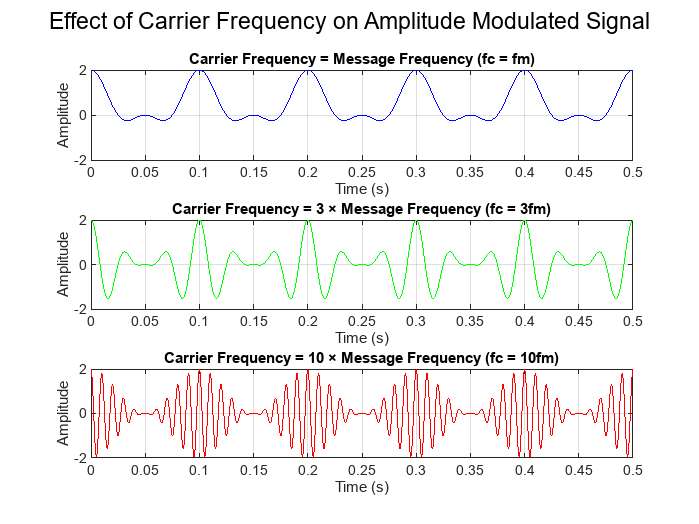

% MATLAB Script: Effect of Carrier Frequency on AM Signal
clc; clear; close all;

% Parameters
Ac = 1;                  % Carrier amplitude
Am = 1;                  % Message amplitude (same for all)
fm = 10;                  % Message frequency (Hz)
t = 0:0.0005:0.5;        % Time vector

% Message signal
m = Am * cos(2*pi*fm*t);

% Carrier frequencies
fc1 = fm;               % Case 1: fc = fm
fc2 = 3*fm;             % Case 2: fc = 3*fm
fc3 = 10*fm;            % Case 3: fc = 10*fm

% AM signals
s1 = (1 + m) .* cos(2*pi*fc1*t);
s2 = (1 + m) .* cos(2*pi*fc2*t);
s3 = (1 + m) .* cos(2*pi*fc3*t);

% Plotting
figure;
subplot(3,1,1);
plot(t, s1, 'b');
title('Carrier Frequency = Message Frequency (fc = fm)');
xlabel('Time (s)');
ylabel('Amplitude');
ylim([-2 2]);
grid on;

subplot(3,1,2);
plot(t, s2, 'g');
title('Carrier Frequency = 3 × Message Frequency (fc = 3fm)');
xlabel('Time (s)');
ylabel('Amplitude');
ylim([-2 2]);
grid on;

subplot(3,1,3);
plot(t, s3, 'r');
title('Carrier Frequency = 10 × Message Frequency (fc = 10fm)');
xlabel('Time (s)');
ylabel('Amplitude');
ylim([-2 2]);
grid on;

sgtitle('Effect of Carrier Frequency on Amplitude Modulated Signal');